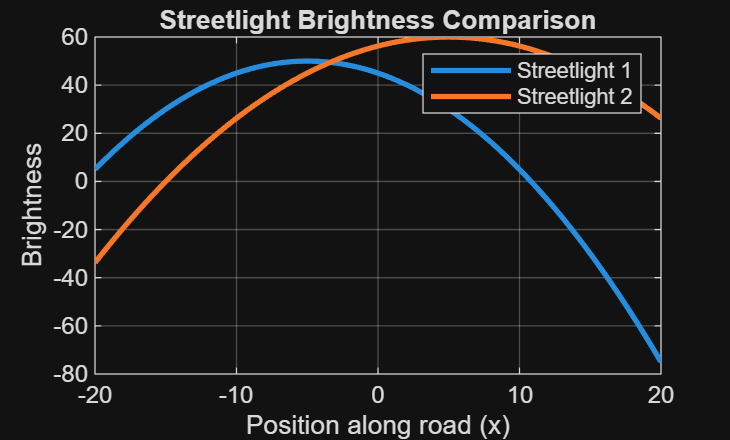

% Zulaikha Khan 
% ES 115 Engineering Computer Applications 
% Module 7 Project: Streetlight Brightness Model 
% Instructor: Lynroy Grant 
% March 28, 2026 
 
clear; clc; close all; 
 
% ---------------------------- 
% Define x values (road position) 
x = -20:0.5:20; 
 
% ---------------------------- 
% Streetlight 1 parameters 
k1 = 0.2; 
h1 = -5; % location of light 
Bmax1 = 50; % max brightness 
 
B1 = -k1*(x - h1).^2 + Bmax1; 
 
% ---------------------------- 
% Streetlight 2 parameters 
k2 = 0.15; 
h2 = 5; % different location 
Bmax2 = 60; % brighter light 
 
B2 = -k2*(x - h2).^2 + Bmax2; 
 
% ---------------------------- 
% Plot both brightness models 
figure; 
plot(x, B1, 'LineWidth', 2); hold on; 
plot(x, B2, 'LineWidth', 2); 
 
title('Streetlight Brightness Comparison'); 
xlabel('Position along road (x)'); 
ylabel('Brightness'); 
legend('Streetlight 1', 'Streetlight 2'); 
grid on; 

 
% ---------------------------- 
% Find maximum brightness points 
 
[max1, idx1] = max(B1); 
x1 = x(idx1); 
 
[max2, idx2] = max(B2); 
x2 = x(idx2); 
 
fprintf('Streetlight 1 max brightness: %.2f at x = %.2f\n', max1, x1); 

Streetlight 1 max brightness: 50.00 at x = -5.00


fprintf('Streetlight 2 max brightness: %.2f at x = %.2f\n', max2, x2); 

Streetlight 2 max brightness: 60.00 at x = 5.00


 
% ---------------------------- 
% Find approximate intersection (equal brightness) 
 
difference = B1 - B2; 
index_intersect = find(abs(difference) < 0.5); 
 
x_intersect = x(index_intersect); 
 
disp('Approximate intersection point(s):'); 

Approximate intersection point(s):


disp(x_intersect)

   -3.5000

